# Database for Upper and Lower Limb Task Based on EEG Signals During the Execution of Motor and Motorimagery Tasks

#### Víctor Asanza, Daniel Montoya, Enrique Peláez, Francis Loayza, Leandro L. Lorente-Leyva, Diego H. Peluffo-Ordóñez and Kleber Gonzalez

- Main Code: [https://github.com/Human-Machine-Interface/OpenBCI_Data_Acquisition](https://github.com/Human-Machine-Interface/OpenBCI_Data_Acquisition)

- `Data Mendeley: `[http://dx.doi.org/10.17632/w9xfz56txv.1](http://dx.doi.org/10.17632/w9xfz56txv.1)

- `More Matlab Examples: `[https://github.com/Human-Machine-Interface](https://github.com/Human-Machine-Interface)

- Hardware: FM=16 chanels , Cyton + Dasy , Campling Rate = 125 Hz

- Subjects: 24

# Raw dataset preparation

clear;clc;%clear all
addpath(genpath('./src'))%functions folders
path = fullfile('./data/');%data folder
folders = FindFolders(path);
allData=[];

# Raw dataset preprocessing

#### % In this example no filtering was done, but it can be done

for i=1:length(folders)% Through all folders
    path1=fullfile(path,folders(i).name);%Select i folder
    filenames = FindCSV(path1);%List All CSV files
    for j=1:length(filenames)% Through all files
        data=readtable(fullfile(path1,filenames(j).name));%Select i CSV file
        dataNew=table2array(data);% Array Double
        dataNew(1,:)=[];%Delete the first row
        dataNew(:,1)=[];%Delete the first column
        DataNorm = fNormalization(dataNew);%Normalization
        Label = fLabelEEG(filenames(j).name);
        DataRMS = [rms(DataNorm) Label];%Feature extraction
        allData=[allData;DataRMS];
        
        % If you want to generate graphs with the EEG data
        %filename=strcat('./figures/',strcat(int2str(i),'_',strcat(int2str(j),strcat('_',num2str(Label)))));
        %fPlotEEG(dataNew,filename);
        %filename=strcat('./figuresNorm/',strcat(int2str(i),'_',strcat(int2str(j),strcat('_',num2str(Label)))));
        %fPlotEEG(DataNorm,filename);
    end
end
%Save .CSV file with all EEG file features
csvwrite('AllDataRMS.csv',allData);

# Plot Raw EEG dataset

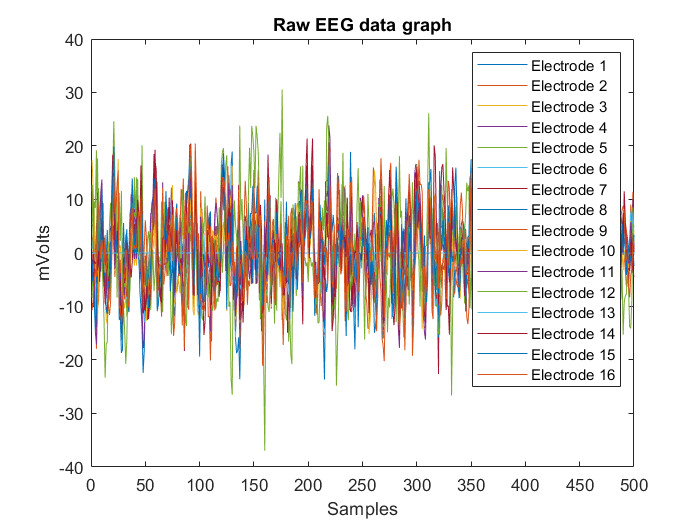

figure
plot(dataNew);xlabel('Samples');ylabel('mVolts');
title('Raw EEG data graph');
legend('Electrode 1','Electrode 2','Electrode 3','Electrode 4','Electrode 5'...
    ,'Electrode 6','Electrode 7','Electrode 8','Electrode 9','Electrode 10'...
    ,'Electrode 11','Electrode 12','Electrode 13','Electrode 14','Electrode 15','Electrode 16');

# Plot Normalization EEG dataset

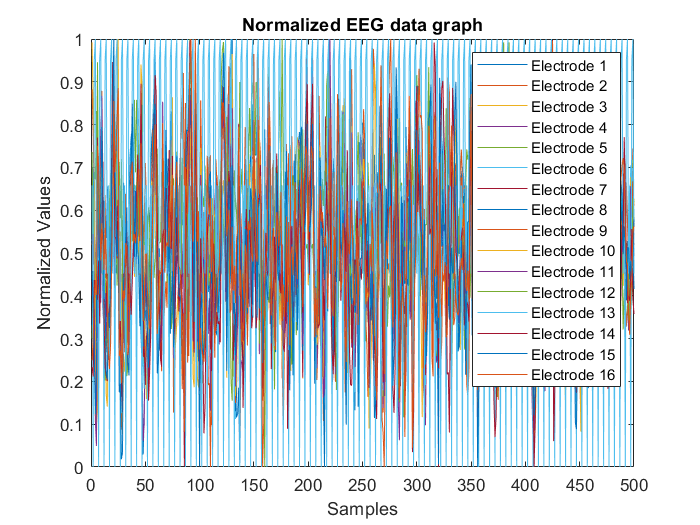

figure
plot(DataNorm);xlabel('Samples');ylabel('Normalized Values');
title('Normalized EEG data graph');
legend('Electrode 1','Electrode 2','Electrode 3','Electrode 4','Electrode 5'...
    ,'Electrode 6','Electrode 7','Electrode 8','Electrode 9','Electrode 10'...
    ,'Electrode 11','Electrode 12','Electrode 13','Electrode 14','Electrode 15','Electrode 16');

# Statistical information of rms in EEG dataset

Electrode_1 = datastats(allData(:,1))%RMS Electrode 1

Electrode_1 = struct with fields:
       num: 2981
       max: 0.8861
       min: 0.1890
      mean: 0.5340
    median: 0.5298
     range: 0.6971
       std: 0.0788


Electrode_2 = datastats(allData(:,2))%RMS Electrode 2

Electrode_2 = struct with fields:
       num: 2981
       max: 0.9146
       min: 0.1357
      mean: 0.5292
    median: 0.5244
     range: 0.7789
       std: 0.0774


Electrode_3 = datastats(allData(:,3))%RMS Electrode 3

Electrode_3 = struct with fields:
       num: 2981
       max: 0.9567
       min: 0.1619
      mean: NaN
    median: NaN
     range: 0.7948
       std: NaN


Electrode_4 = datastats(allData(:,4))%RMS Electrode 4

Electrode_4 = struct with fields:
       num: 2981
       max: 0.9053
       min: 0.1402
      mean: NaN
    median: NaN
     range: 0.7651
       std: NaN


Electrode_5 = datastats(allData(:,5))%RMS Electrode 5

Electrode_5 = struct with fields:
       num: 2981
       max: 0.9000
       min: 0.1671
      mean: 0.5320
    median: 0.5291
     range: 0.7328
       std: 0.0766


Electrode_6 = datastats(allData(:,6))%RMS Electrode 6

Electrode_6 = struct with fields:
       num: 2981
       max: 0.8975
       min: 0.0874
      mean: 0.5425
    median: 0.5344
     range: 0.8101
       std: 0.0818


Electrode_7 = datastats(allData(:,7))%RMS Electrode 7

Electrode_7 = struct with fields:
       num: 2981
       max: 0.9111
       min: 0.1167
      mean: 0.5303
    median: 0.5263
     range: 0.7944
       std: 0.0733


Electrode_8 = datastats(allData(:,8))%RMS Electrode 8

Electrode_8 = struct with fields:
       num: 2981
       max: 0.9611
       min: 0.1668
      mean: 0.5336
    median: 0.5301
     range: 0.7943
       std: 0.0706


Electrode_9 = datastats(allData(:,9))%RMS Electrode 9

Electrode_9 = struct with fields:
       num: 2981
       max: 0.9575
       min: 0.0676
      mean: 0.5320
    median: 0.5277
     range: 0.8900
       std: 0.0820


Electrode_10 = datastats(allData(:,10))%RMS Electrode 10

Electrode_10 = struct with fields:
       num: 2981
       max: 0.9677
       min: 0.0892
      mean: 0.5270
    median: 0.5219
     range: 0.8785
       std: 0.0798


Electrode_11 = datastats(allData(:,11))%RMS Electrode 11

Electrode_11 = struct with fields:
       num: 2981
       max: 0.9085
       min: 0.1198
      mean: 0.5464
    median: 0.5383
     range: 0.7887
       std: 0.0894


Electrode_12 = datastats(allData(:,12))%RMS Electrode 12

Electrode_12 = struct with fields:
       num: 2981
       max: 0.9267
       min: 0.1721
      mean: 0.5329
    median: 0.5284
     range: 0.7546
       std: 0.0739


Electrode_13 = datastats(allData(:,13))%RMS Electrode 13

Electrode_13 = struct with fields:
       num: 2981
       max: 0.9277
       min: 0.1519
      mean: NaN
    median: NaN
     range: 0.7758
       std: NaN


Electrode_14 = datastats(allData(:,14))%RMS Electrode 14

Electrode_14 = struct with fields:
       num: 2981
       max: 0.9266
       min: 0.1919
      mean: 0.5365
    median: 0.5332
     range: 0.7347
       std: 0.0731


Electrode_15 = datastats(allData(:,15))%RMS Electrode 15

Electrode_15 = struct with fields:
       num: 2981
       max: 0.9104
       min: 0.0901
      mean: 0.5368
    median: 0.5290
     range: 0.8204
       std: 0.0820


Electrode_16 = datastats(allData(:,16))%RMS Electrode 16

Electrode_16 = struct with fields:
       num: 2981
       max: 0.9086
       min: 0.0792
      mean: 0.5383
    median: 0.5308
     range: 0.8294
       std: 0.0765


# Feature Selection

DataFeatures=allData(:,1:16);
%corrplot(DataNorm)
R = corrcoef(DataFeatures)

R =     1.0000    0.3258    0.0505    0.1336    0.3021    0.4249    0.2972   -0.0915    0.0580    0.0687    0.0821   -0.0418    0.1364    0.0315    0.0870   -0.0173
    0.3258    1.0000    0.1169    0.2849    0.3231    0.4410    0.3995    0.0498    0.0077   -0.0133    0.0613   -0.0636    0.1091    0.1670    0.1403   -0.0105
    0.0505    0.1169    1.0000    0.2200   -0.1182    0.0962    0.1569    0.2449   -0.1384   -0.0554   -0.0643   -0.0040    0.7787    0.0647   -0.0014    0.0097
    0.1336    0.2849    0.2200    1.0000    0.2037    0.3318    0.4034    0.2891    0.0303    0.1849    0.1648    0.2064    0.0261    0.3143    0.0088    0.2019
    0.3021    0.3231   -0.1182    0.2037    1.0000    0.3632    0.3192   -0.0652   -0.0375    0.0053    0.1733   -0.0814    0.0162    0.1058    0.1585    0.1252
    0.4249    0.4410    0.0962    0.3318    0.3632    1.0000    0.7088    0.2830    0.0467    0.0585    0.2663    0.0656    0.1322    0.2212    0.2268    0.1163
    0.2972    0.3995    0.1569

# Motor Task Classification (Label + 8)

All Classifications Results:

- 2) upper limbs task (Ensemble Subspace KNN) 54.7%

- 3) Lower limbs task (Fine KNN) 43.7%

- **4) Right Upper limbs task (Ensemble Subspace KNN) 73.3%**

- **5) Left Upper limbs task (Ensemble Subspace KNN) 74.6%**

- 6) Right Lower limbs task (Fine KNN) 58.3%

- **7) Right Lower limbs task Dorsal (SVM Cubic SVM) 73.8%**

- **8) Right Lower limbs task Plantar (Ensemble Subspace KNN) 73.3%**

- 9) Left Lower limbs task (Cubic SVM) 55.6%

- **10) Left Lower limbs task Dorsal (Medium Neural Network) 73.3%**

- 11) Left Lower limbs task Plantar (Fine KNN) 67.9%

clear;clc;
% Upload .CSV file with the features of all EEG files
path = fullfile('./data/');%data folder
allData = fLoad_EEG_csv(path,'AllDataRMS.csv');

%[ILCH, IRCH, ILDF, ILPF, IRDF, IRPF, IDesc, idxMaxI] = fIdxLabelEEG_I(allData);
[MLCH, MRCH, MLDF, MLPF, MRDF, MRPF, MDesc, idxMaxM] = fIdxLabelEEG_M(allData);

num = input('Enter a number: ');
switch num
    case 1 %all task
        idx = [MLCH(1:idxMaxM);MRCH(1:idxMaxM);MLDF(1:idxMaxM);MLPF(1:idxMaxM);...
            MRDF(1:idxMaxM);MRPF(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('All task')%-->KNN(Coarse KNN) 23.8%
    case 2 %upper limbs task
        idx = [MLCH(1:idxMaxM);MRCH(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('Upper Limbs task')%--> KNN(Weighted KNN) 50.7%
    case 3 %Lower limbs task
        idx = [MLDF(1:idxMaxM);MLPF(1:idxMaxM);MRDF(1:idxMaxM);MRPF(1:idxMaxM);...
            MDesc(1:idxMaxM)];
        disp('Lower Limbs task')%--> Ensemble (Boosted Trees) 31.5%
    case 4 %Right Upper limbs task
        idx = [MRCH(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('Right Upper limbs task')%--> Tree (fine Tree, medium tree) 70.7%
    case 5 %Left Upper limbs task
        idx = [MLCH(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('Left Upper limbs task')%--> SVM (Medium Gaussian VM) 78%
    case 6 %Right Lower limbs task
        idx = [MRDF(1:idxMaxM);MRPF(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('Right Lower limbs task')%--> Ensemble (Subspace KNN, RUSBoosted KNN) 51.6%
    case 7 %Right Lower limbs task Dorsal
        idx = [MRDF(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('Right Lower limbs task Dorsal')%--> Ensemble (Subspace KNN) 74%
    case 8 %Right Lower limbs task Plantar
        idx = [MRPF(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('Right Lower limbs task Plantar')%--> SVM (Quadratic) 76.7%
    case 9 %Left Lower limbs task
        idx = [MLDF(1:idxMaxM);MLPF(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('Left Lower limbs task')%-->  KNN (Weighted) 53.8%
    case 10 %Left Lower limbs task Dorsal
        idx = [MLDF(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('Left Lower limbs task Dorsal')%--> SVM (Quadratic SVM) 76%
    case 11 %Left Lower limbs task Plantar
        idx = [MLPF(1:idxMaxM);MDesc(1:idxMaxM)];
        disp('Left Lower limbs task Plantar')%--> Ensemble (Subspace KNN) 77%
    otherwise
        disp('other value')
end

MotorData=allData(idx,:);

# Imagery Task Classification (Label)

All Classification Results: 

- 2) upper limbs task (Weighted KNN) 55.3%

- 3) Lower limbs task (Weighted KNN) 40.8%

- 4) Right Upper limbs task (Quadratic Discriminant) 67.5%

- **5) Left Upper limbs task (Fine KNN) 71.7%**

- 6) Right Lower limbs task (Weighted KNN) 55.0%

- 7) Right Lower limbs task Dorsal (Weighted KNN) 69.2%

- **8) Right Lower limbs task Plantar (Fine KNN) 75.8%**

- 9) Left Lower limbs task (Weighted KNN) 52.8%

- **10) Left Lower limbs task Dorsal (Quadratic Discriminant) 70.4%**

- 11) Left Lower limbs task Plantar (Medium Gaussian SVM) 67.9%

clear;clc;
% Upload .CSV file with the features of all EEG files
path = fullfile('./data/');%data folder
allData = fLoad_EEG_csv(path,'AllDataRMS.csv');

[ILCH, IRCH, ILDF, ILPF, IRDF, IRPF, IDesc, idxMaxI] = fIdxLabelEEG_I(allData);
%[MLCH, MRCH, MLDF, MLPF, MRDF, MRPF, MDesc, idxMaxM] = fIdxLabelEEG_M(allData);

num = input('Enter a number: ');
switch num
    case 1%all task
        idx = [ILCH(1:idxMaxI);IRCH(1:idxMaxI);ILDF(1:idxMaxI);ILPF(1:idxMaxI);...
            IRDF(1:idxMaxI);IRPF(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('All task')%--> KNN (Weighted KNN) 21.9%
    case 2%upper limbs task
        idx = [ILCH(1:idxMaxI);IRCH(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('Upper Limbs task')%--> Ensemble (Boosted Trees) 47.6%
    case 3%Lower limbs task
        idx = [ILDF(1:idxMaxI);ILPF(1:idxMaxI);IRDF(1:idxMaxI);IRPF(1:idxMaxI);...
            IDesc(1:idxMaxI)];
        disp('Lower Limbs task')%--> Ensemble (Suspace KNN) 30.1%
    case 4 %Right Upper limbs task
        idx = [IRCH(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('Right Upper limbs task')%--> KNN (Weighted KNN) 71.3%
    case 5 %Left Upper limbs task
        idx = [ILCH(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('Left Upper limbs task')%--> Ensemble (Bagged Trees) 66.7%
    case 6 %Right Lower limbs task
        idx = [IRDF(1:idxMaxI);IRPF(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('Right Lower limbs task')%--> Ensemble (Subspace KNN) 48.4%
    case 7 %Right Lower limbs task Dorsal
        idx = [IRDF(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('Right Lower limbs task Dorsal')%--> Ensemble (Subspace KNN) 70.7%
    case 8 %Right Lower limbs task Plantar
        idx = [IRPF(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('Right Lower limbs task Plantar')%--> Ensemble (Subspace KNN) 78%
    case 9 %Left Lower limbs task
        idx = [ILDF(1:idxMaxI);ILPF(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('Left Lower limbs task')%--> Naiveyes (Gaussian Naive yes) 47.6%
    case 10 %Left Lower limbs task Dorsal
        idx = [ILDF(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('Left Lower limbs task Dorsal')%--> Quadratic (Quadratic Discriminant) 68%
    case 11 %Left Lower limbs task Plantar
        idx = [ILPF(1:idxMaxI);IDesc(1:idxMaxI)];
        disp('Left Lower limbs task Plantar')%--> Ensemble (Bagged Trees) 68%
    otherwise
        disp('other value')
end

Left Lower limbs task Plantar



ImageryData=allData(idx,:);